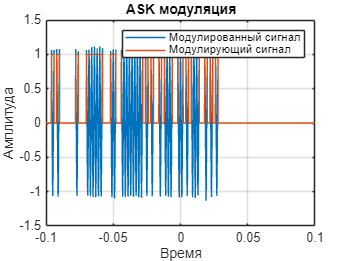

clear , clc , close all
sps = 4;                % Увеличение количества выборок на символ
M = 16;                 % Глубина модуляции
k = log2(M);            % Кол-во битов на символ
EbNoVec = (1:11);       % величина Eb/No (dB)
numSymPerFrame = 2^4;  % Кол-во КАМ символов в кадре

dataIn = randi([0 1],numSymPerFrame*k,1);
fs = 10^6;
ts = -0.1 : 1/ fs : 0.1 -1/ fs ;
N = length ( ts ) ;
%% несущая частота
fc = cos (2* pi *500* ts ) ;
fc = awgn ( fc ,30) ;

 %% модулирующий сигнал
 % длина одного бита в отсчётах
 n_for_bit = 2000;
 % кодируемая последовательность
 %code = [1 0.1 0.1 1 1 0.1 1 0.1 1 1];

 % формируем модулирующий сигнал
 fm = zeros (1 , N ) ;
 for i =1: length ( dataIn )
 for j = n_for_bit *( i -1) +1: n_for_bit * i
 fm ( j ) = dataIn ( i ) ;
 end
 end

 %% амплитудная модуляция
 x = fc .* fm ;
 time = -0.1: 1/2*fs:0 -  1/ fs;
 plot ( ts , x ) , grid on , hold on
 plot ( ts , fm ) , grid on
 title ('ASK модуляция')
 xlabel ('Время') , ylabel ('Амплитуда')
 legend ({ 'Модулированный сигнал';'Модулирующий сигнал'})

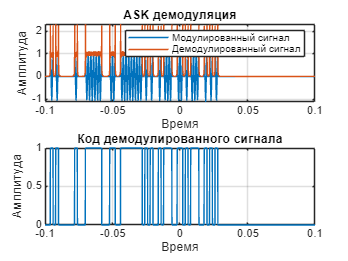


 h = hilbert(x);
 figure
 subplot (2 ,1 ,1)
 plot ( ts ,x) , grid on , hold on
 plot ( ts , abs ( h )) , grid on
 title ('ASK демодуляция')
 xlabel ('Время') , ylabel ('Амплитуда')
 legend ({ 'Модулированный сигнал';'Демодулированный сигнал'})

 % компаратор
 dem = zeros(1,length(h));
 for i = 1:length(h)
    if abs(h(i)) >= 0.5
        dem(i) = 1;
    else
        dem(i) = 0;
    end
 end
 subplot (2 ,1 ,2)
 plot ( ts , dem) , grid on
 title ('Код демодулированного сигнала')
 xlabel ('Время') , ylabel ('Амплитуда')